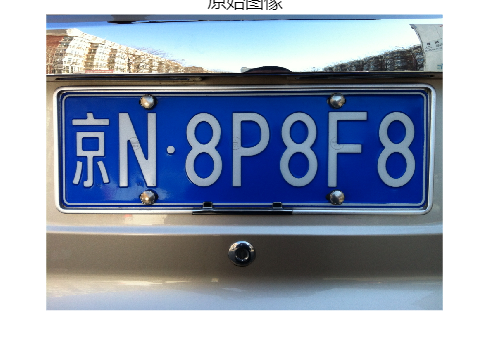

clc;
clearvars; % 更安全的清除方式
close all;

workspace; % 显示工作区面板

% 读取并显示原始图像
I = imread('R---C.jpg');
figure, imshow(I), title('原始图像');

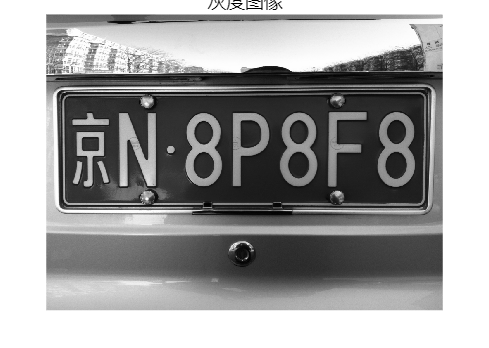


% 转换为灰度图像并显示
Igray = rgb2gray(I);
figure, imshow(Igray), title('灰度图像');

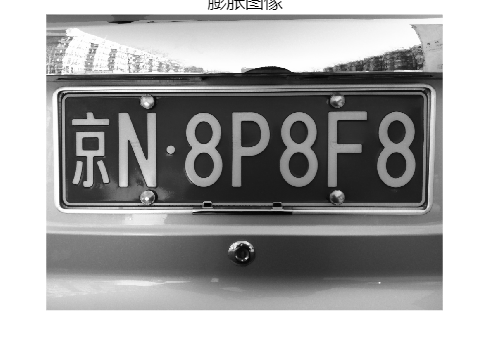


% 使用内置函数进行图像膨胀以去除噪声
se = strel('disk', 1);
Idilate = imdilate(Igray, se);
figure, imshow(Idilate), title('膨胀图像');


% 初始化变量
[rows, cols] = size(Igray);
difference = uint32(0);
max_horz = 0;
maximum = 0;
total_sum = 0;
horz1 = zeros(1, cols);

% 处理水平方向边缘
disp('处理水平方向边缘...');

处理水平方向边缘...


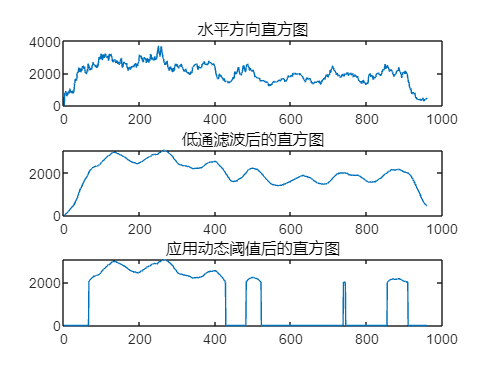

for i = 2:cols
    sum = 0;
    for j = 2:rows
        difference = uint32(abs(int16(Idilate(j, i)) - int16(Idilate(j-1, i))));
        if difference > 20
            sum = sum + difference;
        end
    end
    horz1(i) = sum;
    if sum > maximum
        max_horz = i;
        maximum = sum;
    end
    total_sum = total_sum + sum;
end
average = total_sum / cols;

% 绘制水平方向直方图
figure;
subplot(3,1,1);
plot(horz1);
title('水平方向直方图');

% 对直方图应用低通滤波
horz = filter(ones(1, 41)/41, 1, horz1);
subplot(3,1,2);
plot(horz);
title('低通滤波后的直方图');

% 应用动态阈值
horz(horz < average) = 0;
subplot(3,1,3);
plot(horz);
title('应用动态阈值后的直方图');


% 处理垂直方向边缘
disp('处理垂直方向边缘...');

处理垂直方向边缘...


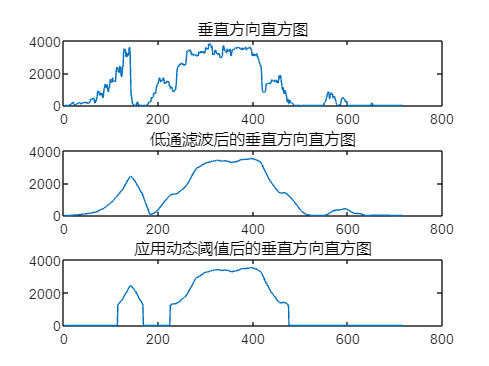

max_vert = 0;
maximum = 0;
total_sum = 0;
vert1 = zeros(rows, 1);

for i = 2:rows
    sum = 0;
    for j = 2:cols
        difference = uint32(abs(int16(Idilate(i, j)) - int16(Idilate(i, j-1))));
        if difference > 20
            sum = sum + difference;
        end
    end
    vert1(i) = sum;
    if sum > maximum
        max_vert = i;
        maximum = sum;
    end
    total_sum = total_sum + sum;
end
average = total_sum / rows;

% 绘制垂直方向直方图
figure;
subplot(3,1,1);
plot(vert1);
title('垂直方向直方图');

% 对垂直方向直方图应用低通滤波
vert = filter(ones(41, 1)/41, 1, vert1);
subplot(3,1,2);
plot(vert);
title('低通滤波后的垂直方向直方图');

% 应用动态阈值
vert(vert < average) = 0;
subplot(3,1,3);
plot(vert);
title('应用动态阈值后的垂直方向直方图');


% 寻找可能的车牌区域
disp('寻找可能的车牌区域...');

寻找可能的车牌区域...


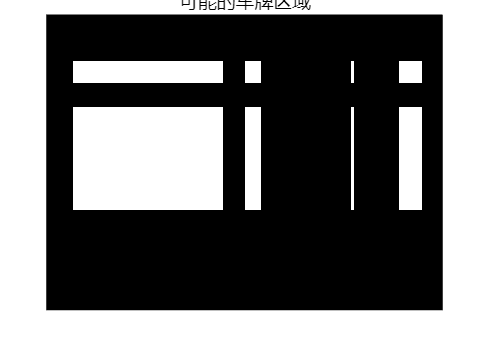

plateRegion = zeros(rows, cols);
for i = 1:rows
    for j = 1:cols
        if horz(j) ~= 0 && vert(i) ~= 0
            plateRegion(i, j) = Igray(i, j);
        end
    end
end

% 显示可能的车牌区域
figure, imshow(plateRegion), title('可能的车牌区域');

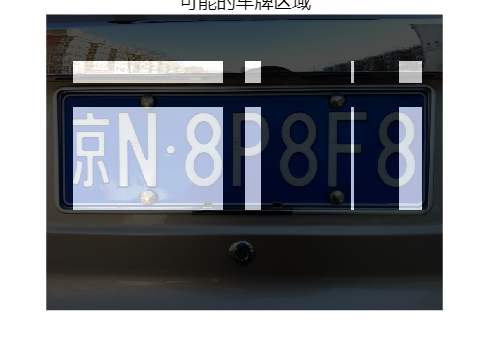

figure, imshow(I); % 首先显示原始图像
hold on; % 保持当前图像，以便在上面添加新内容

% 创建一个与原始图像大小相同的全黑图像
overlay = zeros(size(I, 1), size(I, 2), 'like', I);

% 将可能的车牌区域覆盖到全黑图像中
overlay(plateRegion ~= 0) = 255;

% 将此黑白图像以一定的透明度叠加在原始图像上
h = imshow(overlay);
set(h, 'AlphaData', 0.7); % 设置透明度，可以调整这个值

title('可能的车牌区域');